# [Example 9 – vehicle location estimation](https://www.kalmanfilter.net/multiExamples.html#ex9)

- 准备数据

% Z 模拟测试数据
z_vec = load("./data_ex9.txt");  % z_vec(:, i) -> z_i
len_z = size(z_vec, 2);

% delta t
dt = 1;  % s

% 加速度的不确定度 Q
sigma_a = 0.2;  % m/s^2

% 测量不确定度，沿着X和Y方向 
sigma_x = 3;
sigma_y = 3;

% F: 状态转移矩阵
tmp = [1, dt, 0.5*dt^2; 0, 1, dt; 0, 0, 1];
F = zeros(6, 6);
F(1:3, 1:3) = tmp;
F(3 + (1:3), 3 + (1:3)) = tmp;
F

F =     1.0000    1.0000    0.5000         0         0         0
         0    1.0000    1.0000         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000    1.0000    0.5000
         0         0         0         0    1.0000    1.0000
         0         0         0         0         0    1.0000



% Q: 过程噪声矩阵
tmp = [dt^4/4, dt^3/2, dt^2/2; dt^3/2 dt^2, dt; dt^2/2, dt, 1];
Q = zeros(6, 6);
Q(1:3, 1:3) = tmp;
Q(3 + (1:3), 3 + (1:3)) = tmp;
Q

Q =     0.2500    0.5000    0.5000         0         0         0
    0.5000    1.0000    1.0000         0         0         0
    0.5000    1.0000    1.0000         0         0         0
         0         0         0    0.2500    0.5000    0.5000
         0         0         0    0.5000    1.0000    1.0000
         0         0         0    0.5000    1.0000    1.0000



% R: 测量噪声矩阵
R = diag([sigma_x^2, sigma_y^2]);
R

R =      9     0
     0     9



% H: 观测矩阵
H = [
    1, 0, 0, 0, 0, 0;
    0, 0, 0, 1, 0, 0;
]

H =      1     0     0     0     0     0
     0     0     0     1     0     0


- 初始化

% X: 状态变量
X = zeros(6, 1);
X

X =      0
     0
     0
     0
     0
     0



% P: 估计不确定度
P = 500 * eye(6);
P

P =    500     0     0     0     0     0
     0   500     0     0     0     0
     0     0   500     0     0     0
     0     0     0   500     0     0
     0     0     0     0   500     0
     0     0     0     0     0   500


- 迭代

X_rec = [];
for i = 1:len_z
    % record
    X_rec = [X_rec, X];
    
    % 1 prediction
    X_hat = F * X;
    P_hat = F * P * F' + Q;
    
    % 2 measurement
    Z = z_vec(:, i);
    
    % 3 update
    % 3.1 Kalman Gain
    K = P_hat * H' / ( H * P_hat * H' + R );
    % 3.2 update
    X = X_hat + K * (Z - H * X_hat);
    P = (eye(6) - K * H) * P_hat * (eye(6) - K * H)' + K * R * K';
end
Y_rec = H * X_rec;

- 可视化

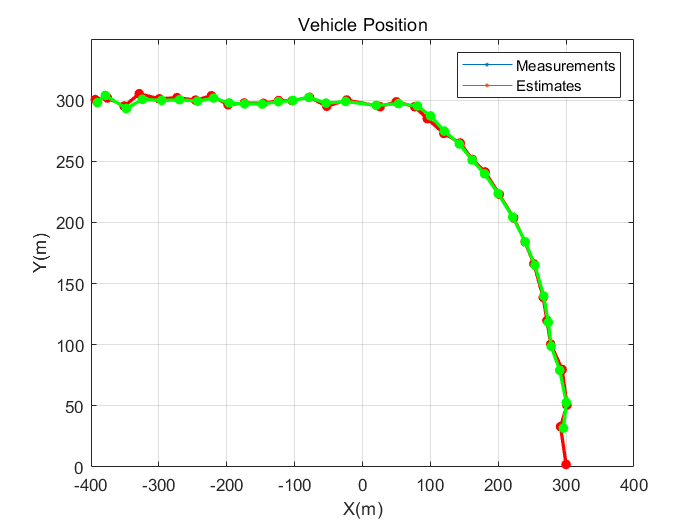

figure(1)
% Z_vec
plot(z_vec(1, :), z_vec(2, :), 'r.-', ...
    'markersize',20, ...
    'linewidth',2)

hold on
% Y_kalman
plot(Y_rec(1, 2:end), Y_rec(2, 2:end), 'g.-', ...
    'markersize',20, ...
    'linewidth',2);

% capital
xlabel("X(m)");
ylabel("Y(m)");
title("Vehicle Position");
grid on
set(gca, 'xtick', -400:100:400);
set(gca, 'ytick', 0:50:320);
legend("Measurements", "Estimates");